**Problem 1**

Red = x

Green = y

Blue = z

clear clc;
syms theta_1 theta_2 theta_3 theta_4 theta_5 real
a1 = 50e-3;
a2 = 93e-3;
a3 = 93e-3;
a4 = 50e-3;
a5 = 45e-3;
a6 = 35e-3;

theta = [theta_1, theta_2, theta_3, theta_4, theta_5];
d = [a1,0,0,0,0];
a = [0,a2,a3,a4,a6];
alpha = [90,0,0,0,0];

A1_0 = dhTransform(theta(1), d(1), a(1), alpha(1))

$$A1\_0 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & \frac{1}{20}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2_1 = dhTransform(theta(2),d(2),a(2),alpha(2))

$$A2\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & \frac{93\,\cos\left(\theta_{2}\right)}{1000}\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & \frac{93\,\sin\left(\theta_{2}\right)}{1000}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3_2 = dhTransform(theta(3),d(3),a(3),alpha(3))

$$A3\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & \frac{93\,\cos\left(\theta_{3}\right)}{1000}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & \frac{93\,\sin\left(\theta_{3}\right)}{1000}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A4_3 = dhTransform(theta(4),d(4),a(4),alpha(4))

$$A4\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & 0 & \frac{\cos\left(\theta_{4}\right)}{20}\\ \sin\left(\theta_{4}\right) & \cos\left(\theta_{4}\right) & 0 & \frac{\sin\left(\theta_{4}\right)}{20}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T4_0 = simplify(A1_0*A2_1*A3_2*A4_3)

$$T4\_0 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(\theta_{1}\right) & -\sigma_{1}\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & \frac{\cos\left(\theta_{1}\right)\,\sigma_{2}}{1000}\\ \sigma_{3}\,\sin\left(\theta_{1}\right) & -\sigma_{1}\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \frac{\sin\left(\theta_{1}\right)\,\sigma_{2}}{1000}\\ \sigma_{1} & \sigma_{3} & 0 & \frac{\sigma_{1}}{20}+\frac{93\,\sin\left(\theta_{2}+\theta_{3}\right)}{1000}+\frac{93\,\sin\left(\theta_{2}\right)}{1000}+\frac{1}{20}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{2}=50\,\sigma_{3}+93\,\cos\left(\theta_{2}+\theta_{3}\right)+93\,\cos\left(\theta_{2}\right)\\ \sigma_{3}=\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$

A5_4 = [1,0,0,a6-a4;
        0,1,0,a5;
        0,0,1,0;
        0,0,0,1];
T5_0 = simplify(T4_0*A5_4)

$$T5\_0 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(\theta_{1}\right) & -\sigma_{2}\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & \frac{\cos\left(\theta_{1}\right)\,\sigma_{1}}{1000}\\ \sigma_{3}\,\sin\left(\theta_{1}\right) & -\sigma_{2}\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \frac{\sin\left(\theta_{1}\right)\,\sigma_{1}}{1000}\\ \sigma_{2} & \sigma_{3} & 0 & \frac{9\,\sigma_{3}}{200}+\frac{7\,\sigma_{2}}{200}+\frac{93\,\sin\left(\theta_{2}+\theta_{3}\right)}{1000}+\frac{93\,\sin\left(\theta_{2}\right)}{1000}+\frac{1}{20}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=35\,\sigma_{3}-45\,\sigma_{2}+93\,\cos\left(\theta_{2}+\theta_{3}\right)+93\,\cos\left(\theta_{2}\right)\\ \sigma_{2}=\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{3}=\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$

**Problem 2**

Decouple after first 3 joints: Oc is O3, 

First joint controls moves the direction of the arm, and is therefore partially responsible for x and y

% We can find theta_1 without doing any decoupling, since theta_1 is the
% only rotational joint in the x-y plane of the base frame
o4 = T4_0(1:3,4);
theta_1 = atan2(o4(2),o4(1));

% Since the robot is 4DOF, and w is given, we can rewrite the x and y
% component of x4_0 as a function of w
x4_0 = T4_0(1:3,1)

$$x4\_0 = \left(\begin{array}{c} \cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\,\cos\left(\theta_{1}\right)\\ \cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\,\sin\left(\theta_{1}\right)\\ \sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}\right)$$

w = x4_0(3);
x4_0 = [sqrt(1-w^2)*cos(theta_1);
    sqrt(1-w^2)*sin(theta_1);
    w]

$$x4\_0 = \begin{array}{l} \left(\begin{array}{c} \frac{\cos\left(\theta_{1}\right)\,\sqrt{1-{\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)}^{2}}\,\sigma_{1}}{\left|\cos\left(\theta_{1}\right)\,\sigma_{1}+\sin\left(\theta_{1}\right)\,\sigma_{1}\,\mathrm{i}\right|}\\ \frac{\sin\left(\theta_{1}\right)\,\sqrt{1-{\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)}^{2}}\,\sigma_{1}}{\left|\cos\left(\theta_{1}\right)\,\sigma_{1}+\sin\left(\theta_{1}\right)\,\sigma_{1}\,\mathrm{i}\right|}\\ \sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=50\,\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)+93\,\cos\left(\theta_{2}+\theta_{3}\right)+93\,\cos\left(\theta_{2}\right) \end{array}$$

% Kinematic decoupling
o3 = o4 - a(4)*x4_0;
oc = o3;

% Matlab says atan2(y,x). Which should i use? ----------------------

% Now we can find theta_2, 3 and 4
s = oc(3) - d(1);
r=sqrt(oc(1)^2+oc(2)^2);
c3 = (r^2 + s^2 - a(2)^2-a(3)^2)/(2*a(2)*a(3));

theta_3 = atan2(sqrt(1-c3^2), c3);
theta_2 = atan2(s,r) - atan2(a(3)*sin(atan2(c3,sqrt(1-c3^2))),a(2)+a(3)*c3);

% Isolate theta_4 from w
theta_4 = asin(w) - (theta_2 + theta_3);


Use problem 3 to check problem 2. They should line up

R=32e-3;
pc_0=[150e-3;0;120e-3];

o4 = pc_0+R*[0;cos(0);sin(0)]

[q1,q2,q3,q4] = Config4DOF(o4, 0, 50e-3, 93e-3, 93e-3, 50e-3)

q1 = 0.2102

q2 = -0.2397

q3 = 1.6699

q4 = -1.4302

T4_0_f = matlabFunction(T4_0);

T4_0_f(q1,q2,q3,q4)

**Problem 3**

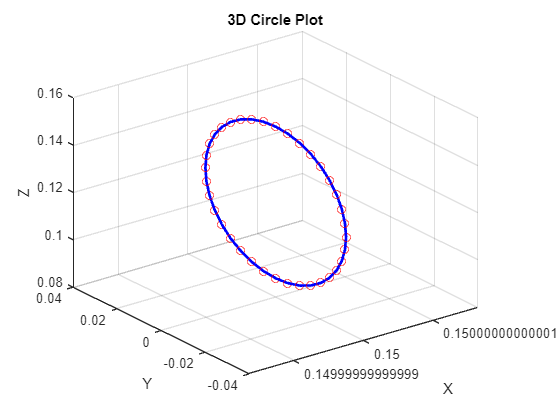

angles = linspace(0,2*pi,37);

x_circle = pc_0(1) * ones(size(angles));
y_circle = R * cos(angles) + pc_0(2); 
z_circle = R * sin(angles) + pc_0(3);

o4_matrix = [x_circle; y_circle; z_circle];
num_points = size(o4_matrix, 2); 

for i = 1:num_points
    o4 = o4_matrix(:, i); 
    [q1, q2, q3, q4] = Config4DOF(o4, 0, 50e-3, 93e-3, 93e-3, 50e-3);
    
    q1_all(i) = q1;
    q2_all(i) = q2;
    q3_all(i) = q3;
    q4_all(i) = q4;

    FK = T4_0_f(q1_all(i),q2_all(i),q3_all(i),q4_all(i));
    
    FK_points(:,i) = FK(1:3,4);

    FK_r = FK(1:3,3);
  
end

figure(1)
plot3(FK_points(1,:),FK_points(2,:),FK_points(3,:),'ro')
hold on
plot3(x_circle, y_circle, z_circle, '-b', 'LineWidth', 2); 
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Circle Plot');

**Problem 4**


T1_0 = simplify(A1_0);
T2_0 = simplify(A1_0*A2_1);
T3_0 = simplify(A1_0*A2_1*A3_2);

o0_j = [0,0,0]';
o1_j = T1_0(1:3,4);
o2_j = T2_0(1:3,4);
o3_j = T3_0(1:3,4);
o4_j = T4_0(1:3,4);
o5_j = T5_0(1:3,4);

o_j_matrix4 = [o0_j, o1_j, o2_j, o3_j, o4_j];
o_j_matrix5 = [o0_j, o1_j, o2_j, o3_j, o5_j];

z0_j = [0,0,1]';
z1_j = T1_0(1:3,3);
z2_j = T2_0(1:3,3);
z3_j = T3_0(1:3,3);
z4_j = T4_0(1:3,3);

z_j_matrix4 = [z0_j, z1_j, z2_j, z3_j];
z_j_matrix5 = [z0_j, z1_j, z2_j, z4_j];


J4 = simplify(Jacobi_Revolute(o_j_matrix4, z_j_matrix4, 5));

$$J = \begin{array}{l} \left(\begin{array}{cccc} -\frac{\sin\left(\theta_{1}\right)\,\sigma_{2}}{1000} & -\cos\left(\theta_{1}\right)\,\sigma_{1} & -\cos\left(\theta_{1}\right)\,\left(\frac{\sigma_{3}}{20}+\sigma_{4}\right) & -\frac{\sigma_{3}\,\cos\left(\theta_{1}\right)}{20}\\ \frac{\cos\left(\theta_{1}\right)\,\sigma_{2}}{1000} & -\sin\left(\theta_{1}\right)\,\sigma_{1} & -\sin\left(\theta_{1}\right)\,\left(\frac{\sigma_{3}}{20}+\sigma_{4}\right) & -\frac{\sigma_{3}\,\sin\left(\theta_{1}\right)}{20}\\ 0 & \frac{\sigma_{6}}{20}+\frac{\sigma_{5}}{1000}+\frac{93\,\cos\left(\theta_{2}\right)}{1000} & \frac{\sigma_{6}}{20}+\frac{\sigma_{5}}{1000} & \frac{\sigma_{6}}{20}\\ 0 & \sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\\ 0 & -\cos\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right)\\ 1 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sigma_{3}}{20}+\sigma_{4}+\frac{93\,\sin\left(\theta_{2}\right)}{1000}\\ \sigma_{2}=50\,\sigma_{6}+\sigma_{5}+93\,\cos\left(\theta_{2}\right)\\ \sigma_{3}=\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{4}=\frac{93\,\sin\left(\theta_{2}+\theta_{3}\right)}{1000}\\ \sigma_{5}=93\,\cos\left(\theta_{2}+\theta_{3}\right)\\ \sigma_{6}=\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$

J5 = Jacobi_Revolute(o_j_matrix5, z_j_matrix5, 5);

$$J = \begin{array}{l} \left(\begin{array}{cccc} -\frac{\sin\left(\theta_{1}\right)\,\sigma_{3}}{1000} & -\cos\left(\theta_{1}\right)\,\sigma_{2} & -\cos\left(\theta_{1}\right)\,\sigma_{4} & -\cos\left(\theta_{1}\right)\,\sigma_{5}\\ \frac{\cos\left(\theta_{1}\right)\,\sigma_{3}}{1000} & -\sin\left(\theta_{1}\right)\,\sigma_{2} & -\sin\left(\theta_{1}\right)\,\sigma_{4} & -\sin\left(\theta_{1}\right)\,\sigma_{5}\\ 0 & \frac{\sigma_{6}}{1000}+\frac{93\,\cos\left(\theta_{2}\right)}{1000}+\sigma_{1} & \frac{\sigma_{6}}{1000}+\sigma_{1} & \sigma_{1}\\ 0 & \sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\\ 0 & -\cos\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right)\\ 1 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{130}\,\cos\left(\theta_{2}+\theta_{3}+\theta_{4}+\mathrm{atan}\left(\frac{9}{7}\right)\right)}{200}\\ \sigma_{2}=\frac{9\,\sigma_{9}}{200}+\frac{7\,\sigma_{8}}{200}+\sigma_{7}+\frac{93\,\sin\left(\theta_{2}\right)}{1000}\\ \sigma_{3}=35\,\sigma_{9}-45\,\sigma_{8}+\sigma_{6}+93\,\cos\left(\theta_{2}\right)\\ \sigma_{4}=\sigma_{7}+\frac{\sqrt{130}\,\cos\left(\theta_{2}+\theta_{3}+\theta_{4}-\mathrm{atan}\left(\frac{7}{9}\right)\right)}{200}\\ \sigma_{5}=\frac{9\,\sigma_{9}}{200}+\frac{7\,\sigma_{8}}{200}\\ \sigma_{6}=93\,\cos\left(\theta_{2}+\theta_{3}\right)\\ \sigma_{7}=\frac{93\,\sin\left(\theta_{2}+\theta_{3}\right)}{1000}\\ \sigma_{8}=\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{9}=\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$


J4_f = matlabFunction(J4);
J5_f = matlabFunction(J5);

q1_0 = q1_all(1);
q2_0 = q2_all(1);
q3_0 = q3_all(1);
q4_0 = q4_all(1);

q1_90 = q1_all(10);
q2_90 = q2_all(10);
q3_90 = q3_all(10);
q4_90 = q4_all(10);

q1_180 = q1_all(19);
q2_180 = q2_all(19);
q3_180 = q3_all(19);
q4_180 = q4_all(19);

q1_270 = q1_all(28);
q2_270 = q2_all(28);
q3_270 = q3_all(28);
q4_270 = q4_all(28);


% NOT USED TILL Q6 %
q1_360 = q1_all(37);
q2_360 = q2_all(37);
q3_360 = q3_all(37);
q4_360 = q4_all(37);
% ---------------- %


J4_0 = J4_f(q1_0,q2_0,q3_0,q4_0);
J4_90 = J4_f(q1_90,q2_90,q3_90,q4_90);
J4_180 = J4_f(q1_180,q2_180,q3_0,q4_180);
J4_270 = J4_f(q1_270,q2_270,q3_270,q4_270);

% NOT USED TILL Q5
J4_360 = J4_f(q1_360,q2_360,q3_360,q4_360);

J5_0 = J5_f(q1_0,q2_0,q3_0,q4_0);
J5_90 = J5_f(q1_90,q2_90,q3_90,q4_90);
J5_180 = J5_f(q1_180,q2_180,q3_0,q4_180);
J5_270 = J5_f(q1_270,q2_270,q3_270,q4_270);



**Problem 5**

q0 = [q1_0, q2_0, q3_0, q4_0];
q1 = [q1_90, q2_90, q3_90, q4_90];
q2 = [q1_180, q2_180, q3_180, q4_180];
q3 = [q1_270, q2_270, q3_270, q4_270];
q4 = [q1_360, q2_360, q3_360, q4_360];


T_problem(:,:,1) = T4_0_f(q0(1),q0(2),q0(3),q0(4));
T_problem(:,:,2) = T4_0_f(q1(1),q1(2),q1(3),q1(4));
T_problem(:,:,3) = T4_0_f(q2(1),q2(2),q2(3),q2(4));
T_problem(:,:,4) = T4_0_f(q3(1),q3(2),q3(3),q3(4));
T_problem(:,:,5) = T4_0_f(q4(1),q4(2),q4(3),q4(4));

v = [0, 0, 0, 0;
    0, -27e-3, 0 ,0;
    0, 0, -27e-3, 0;
    0, 27e-3, 0, 0;
    0,0,0,0];

JJ(:,:,1) = J4_0;
JJ(:,:,2) = J4_90;
JJ(:,:,3) = J4_180;
JJ(:,:,4) = J4_270;
JJ(:,:,5) = J4_360;

for i = 1:5

    Ryx = T_problem(2,1,i);
    Rxx = T_problem(1,1,i);
    Mask = [1,0,0,0,0,0;
            0,1,0,0,0,0;
            0,0,1,0,0,0;
            0,0,0,Ryx, -Rxx, 0];
    A4x6 = JJ(:,:,i);
    A4x4 = Mask*JJ(:,:,i);
    J_plus = ((transpose(A4x4)*A4x4)^-1)*transpose(A4x4);     % Underactuated arm (4 DOF < 6 DOF)
    q_dot(:,i) = J_plus*v(i,:)';

end


q_dot




**Problem 6**



q0d = q_dot(:,1)';
q0dd = [0,0,0,0];


q1d = q_dot(:,2)';
q1dd = [0,0,0,0];


q2d = q_dot(:,3)';
q2dd = [0,0,0,0];


q3d = q_dot(:,4)';
q3dd = [0,0,0,0];


q4d = q_dot(:,5)';
q4dd = [0,0,0,0];



t0 = 0;
t1 = 2;

C_0 = Trajectory_interpolation(t0, t1, q0, q0d, q0dd, q1, q1d, q1dd)
C_90 = Trajectory_interpolation(t0, t1, q1, q1d, q1dd, q2, q2d, q2dd)
C_180 = Trajectory_interpolation(t0, t1, q2, q2d, q2dd, q3, q3d, q3dd)
C_270 = Trajectory_interpolation(t0, t1, q3, q3d, q3dd, q4, q4d, q4dd)


**Problem 7**

t = linspace(0,2,100);
q_0_1 = C_0(1,1)+C_0(1,2)*t+C_0(1,3)*t.^2+C_0(1,4)*t.^3+C_0(1,5)*t.^4+C_0(1,6)*t.^5;
q_0_2 = C_0(2,1)+C_0(2,2)*t+C_0(2,3)*t.^2+C_0(2,4)*t.^3+C_0(2,5)*t.^4+C_0(2,6)*t.^5;
q_0_3 = C_0(3,1)+C_0(3,2)*t+C_0(3,3)*t.^2+C_0(3,4)*t.^3+C_0(3,5)*t.^4+C_0(3,6)*t.^5;
q_0_4 = C_0(4,1)+C_0(4,2)*t+C_0(4,3)*t.^2+C_0(4,4)*t.^3+C_0(4,5)*t.^4+C_0(4,6)*t.^5;

figure(2)
plot(t, f_90_1,'-b',t,f_90_4,'-r');

**Problem 8**

% Initialize array to store condition numbers
cond_values = zeros(1, num_points);

% Calculate condition numbers for each point
for i = 1:num_points
    cond_values(i) = cond(J4_f(q1_all(i), q2_all(i), q3_all(i), q4_all(i)));
end
figure(3)
plot(angles, cond_values)
xlabel("Circle Point (Radians)")
ylabel("Cond Value of Jacobian")

